**Dependecies: **

Matlab packages:

mapping toolbox

isconnection

database toolbox

json file : [Download | pgJDBC (postgresql.org)](https://jdbc.postgresql.org/download/)

- Connect to the SQL datbase

- Access a table in the database

clear;
close ALL FORCE;
clc;


javaaddpath('C:\Users\jaina.DESKTOP-D1USSUU\Downloads\postgresql-42.7.3.jar');
dburl = 'jdbc:postgresql://localhost:5432/bigdata';
%datasource="PostgreSQL ODBC"
username = 'bigdata';
password = 'tImPgDBfBDc!32#';

conn = database('bigdata',username,password,'org.postgresql.Driver', dburl)

conn =   connection with properties:

                  DataSource: 'bigdata'
                    UserName: 'bigdata'
                      Driver: 'org.postgresql.Driver'
                         URL: 'jdbc:postgresql://localho ...'
                     Message: ''
                        Type: 'JDBC Connection Object'
  Database Properties:

                  AutoCommit: 'on'
                    ReadOnly: 'off'
                LoginTimeout: 0
      MaxDatabaseConnections: 8192

  Catalog and Schema Information:

              DefaultCatalog: 'bigdata'
                    Catalogs: {'bigdata', 'postgres', 'template1'}
                     Schemas: {'information_schema', 'pg_catalog', 'public'}

  Database and Driver Information:

         DatabaseProductName: 'PostgreSQL'
      DatabaseProductVersion: '16.1 (Debian 16.1-1.pgdg1 ...'
                  DriverName: 'PostgreSQL JDBC Driver'
               

%conn = database('bigdata',username,password,'org.postgresql.Driver', dburl)

tablename = 'densities';
data = sqlread(conn, tablename);

disp(head(data, 3)); % Display the first 3 rows of the data

    measurementID    month    day    year    bdaID    stationID    intensityID    taxaID    density         measurementDate     
    _____________    _____    ___    ____    _____    _________    ___________    ______    _______    _________________________

          1            5      11     2021      0          1           {'1'}         0        3.5413    {'2021-05-11 00:00:00.0'}
          2            5      11     2021      0          1           {'1'}         1       0.30139    {'2021-05-11 00:00:00.0'}
          3            5      11     2021      0          1           {'1'}         2             0    {'2021-05-11 00:00:00.0'}




% sqlquery = "SELECT * FROM densities";  % alterate code that does the same thing
% data = fetch(conn,sqlquery);
% head(data,5)


% %addpath(genpath('C:\Users\Naomi Jainarine\Documents\Matlab files\add ons')); %package location
% %addpath 'C:\Users\Naomi Jainarine\Documents\Dissertation\Dissertation Matlab files\Dredging Impacts Interim Analyses' %file location


 3.  Now let's view our fetched data to a MATLAB table and access specific columns for analysis

% Display the MATLAB table
disp('MATLAB table:');

MATLAB table:


disp(data);

    measurementID    month    day    year    bdaID    stationID    intensityID    taxaID    density          measurementDate     
    _____________    _____    ___    ____    _____    _________    ___________    ______    ________    _________________________

           1            5      11    2021       0          1          {'1'}          0        3.5413    {'2021-05-11 00:00:00.0'}
           2            5      11    2021       0          1          {'1'}          1       0.30139    {'2021-05-11 00:00:00.0'}
           3            5      11    2021       0          1          {'1'}          2             0    {'2021-05-11 00:00:00.0'}
         



month = data.month; % Replace 'ColumnName' with the actual column name
day= data.day;
year=data.year;
sta=data.stationID

sta =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


dre_int=data.intensityID

dre_int = 1108×1 cell array
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}


taxa=data.taxaID

taxa =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


taxa_den=data.density

taxa_den = 1.0e+03 *

    0.0035
    0.0003
         0
    0.0208
    0.0686
         0
    0.0018
    0.0185
    0.0003
    0.0041


dre_per=data.bdaID

dre_per =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


4. now let's combine our date columns to a julian date variable. Note: It is better to upload dates in 3 columns (month, day ,year) and group later on .

dt=datetime(year,month,day);
jday=juliandate(dt);
%typing   length(unique(jday)) into the command window will tell you how many individual sampling dates you have.

5. Grouping total Zooplankton density by dredging period and intensity. Stations of the same dredging intensity and dredging period were averaged together

% "23" represents zooplankton total for that sampling day

tot_zoo=find(taxa==23);
taxa2=taxa(tot_zoo);
month2=month(tot_zoo);
day2=day(tot_zoo);
taxa_zoo2=taxa_den(tot_zoo);
jday2=jday(tot_zoo);
sta2=sta(tot_zoo);
dre_per2=dre_per(tot_zoo);
dre_int2=dre_int(tot_zoo);


% Check the data type of dre_int2
is_numeric = isnumeric(dre_int2);

if ~is_numeric
    % Convert dre_int2 to numeric if it's not already
    dre_int2 = str2double(dre_int2);
    
    % Check if conversion was successful
    if any(isnan(dre_int2))
        error('Conversion to numeric failed. Data contains non-numeric values.');
    end
end

T= table(sta2,taxa_zoo2,dre_int2,dre_per2);

s= findgroups(dre_per2,dre_int2);

tot_zoo_dens = splitapply(@mean,taxa_zoo2,s);
tot_dre_period = splitapply(@mean,dre_per2,s);
tot_dre_intensity = splitapply(@mean,dre_int2,s);

6. Let's use our new table to make a bargraph

new_bar=[];
new_bar(1,:) = tot_zoo_dens(tot_dre_period==0)

new_bar = 1.0e+03 *

    1.1439    1.3445    0.1461


new_bar(2,:) = tot_zoo_dens(tot_dre_period==1)

new_bar = 1.0e+03 *

    1.1439    1.3445    0.1461
    0.6202    0.9646    0.5250


new_bar(3,:) = tot_zoo_dens(tot_dre_period==2)

new_bar = 1.0e+03 *

    1.1439    1.3445    0.1461
    0.6202    0.9646    0.5250
    0.5982    0.8707    0.2662


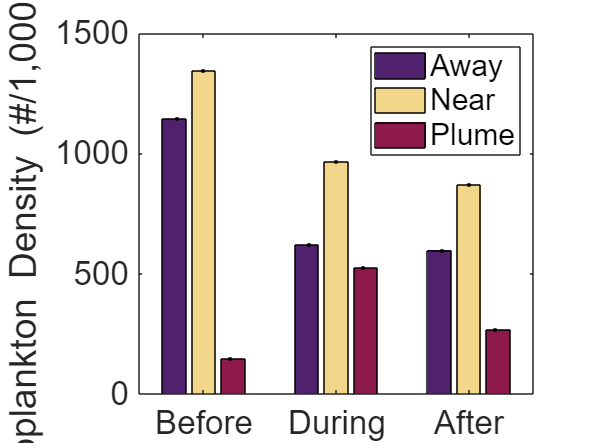


figure;
bar1=bar(new_bar, 'grouped');

ci_away_bef=(std(tot_zoo_dens(tot_dre_intensity==0 & tot_dre_period==0))./sqrt(length(tot_zoo_dens(tot_dre_intensity==0 & tot_dre_period==0))))*1.96;
ci_near_bef=(std(tot_zoo_dens(tot_dre_intensity==1 & tot_dre_period==0))./sqrt(length(tot_zoo_dens(tot_dre_intensity==1 & tot_dre_period==0))))*1.96;
ci_plume_bef=(std(tot_zoo_dens(tot_dre_intensity==2 & tot_dre_period==0))./sqrt(length(tot_zoo_dens(tot_dre_intensity==2 & tot_dre_period==0))))*1.96;

ci_away_dur=(std(tot_zoo_dens(tot_dre_intensity==0 & tot_dre_period==1))./sqrt(length(tot_zoo_dens(tot_dre_intensity==0 & tot_dre_period==1))))*1.96;
ci_near_dur=(std(tot_zoo_dens(tot_dre_intensity==1 & tot_dre_period==1))./sqrt(length(tot_zoo_dens(tot_dre_intensity==1 & tot_dre_period==1))))*1.96;
ci_plume_dur=(std(tot_zoo_dens(tot_dre_intensity==2 & tot_dre_period==1))./sqrt(length(tot_zoo_dens(tot_dre_intensity==2 & tot_dre_period==1))))*1.96;

ci_away_aft=(std(tot_zoo_dens(tot_dre_intensity==0 & tot_dre_period==2))./sqrt(length(tot_zoo_dens(tot_dre_intensity==0 & tot_dre_period==2))))*1.96;
ci_near_aft=(std(tot_zoo_dens(tot_dre_intensity==1 & tot_dre_period==2))./sqrt(length(tot_zoo_dens(tot_dre_intensity==1 & tot_dre_period==2))))*1.96;
ci_plume_aft=(std(tot_zoo_dens(tot_dre_intensity==2 & tot_dre_period==2))./sqrt(length(tot_zoo_dens(tot_dre_intensity==2 & tot_dre_period==2))))*1.96;

ci_vec_tot_det=[ci_away_bef,ci_near_bef,ci_plume_bef;ci_away_dur,ci_near_dur,ci_plume_dur;ci_away_aft,ci_near_aft,ci_plume_aft];
hold on;
errorbar([0.8,1,1.2;1.8,2,2.2; 2.8,3,3.2],new_bar,ci_vec_tot_det,'.k');
hold on;
legend([bar1(1),bar1(2),bar1(3)],{'Away','Near','Plume'});
set(gca,'xtick',[1:3],'xticklabel',{'Before','During','After'});
ylabel('Zooplankton Density (#/1,000 m^3)');
set(gca,'fontsize',20);


set(bar1(1),'FaceColor', "#50216D")
set(bar1(2),'FaceColor', "#F2D78A")
set(bar1(3),'FaceColor', "#8E1A4C")

Stats -2way anova

ZIP stands for Zooplankton Dredging Intensity and Period

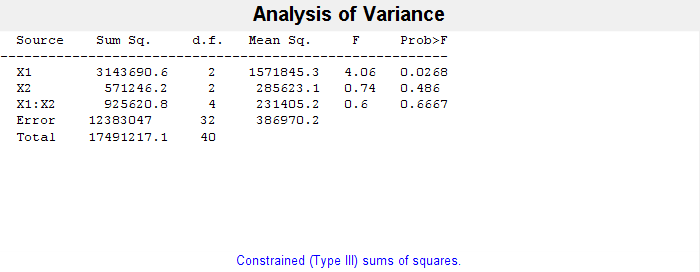


[P,T,STATS,TERMS]= anovan(taxa_zoo2,[dre_int2,dre_per2],'model','interaction');

X1 = Intensity 

X2 = Period

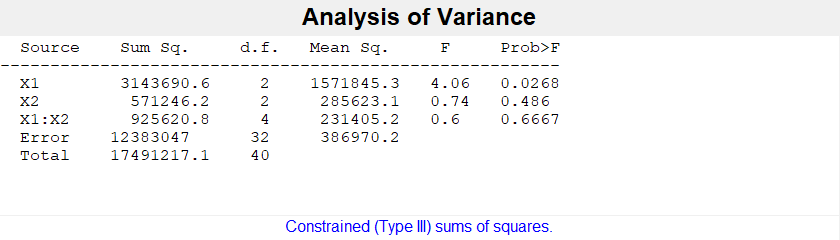

7. oops! We forgot to log our results! 

new_bar=[];
new_bar(1,:) = log(tot_zoo_dens(tot_dre_period==0))+0.1

new_bar =     7.1422    7.3038    5.0843


new_bar(2,:) = log(tot_zoo_dens(tot_dre_period==1))+0.1

new_bar =     7.1422    7.3038    5.0843
    6.5301    6.9717    6.3634


new_bar(3,:) = log(tot_zoo_dens(tot_dre_period==2))+0.1

new_bar =     7.1422    7.3038    5.0843
    6.5301    6.9717    6.3634
    6.4939    6.8694    5.6843


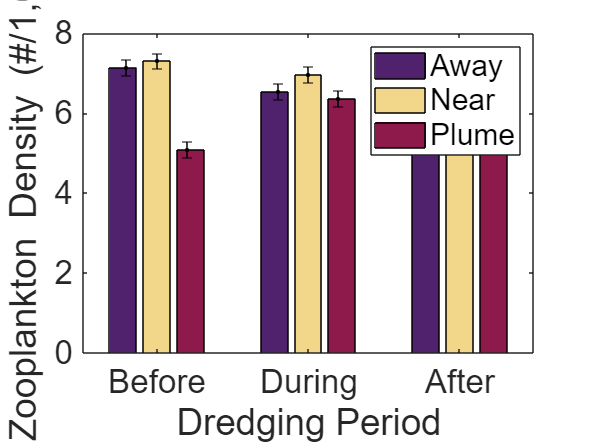


figure;
bar1=bar(new_bar, 'grouped');

ci_away_bef=(std(log(tot_zoo_dens(tot_dre_intensity==0 & tot_dre_period==0)))+0.1./sqrt(length(tot_zoo_dens(tot_dre_intensity==0 & tot_dre_period==0))))*1.96;
ci_near_bef=(std(log(tot_zoo_dens(tot_dre_intensity==1 & tot_dre_period==0)))+0.1./sqrt(length(tot_zoo_dens(tot_dre_intensity==1 & tot_dre_period==0))))*1.96;
ci_plume_bef=(std(log(tot_zoo_dens(tot_dre_intensity==2 & tot_dre_period==0)))+0.1./sqrt(length(tot_zoo_dens(tot_dre_intensity==2 & tot_dre_period==0))))*1.96;

ci_away_dur=(std(log(tot_zoo_dens(tot_dre_intensity==0 & tot_dre_period==1)))+0.1./sqrt(length(tot_zoo_dens(tot_dre_intensity==0 & tot_dre_period==1))))*1.96;
ci_near_dur=(std(log(tot_zoo_dens(tot_dre_intensity==1 & tot_dre_period==1)))+0.1./sqrt(length(tot_zoo_dens(tot_dre_intensity==1 & tot_dre_period==1))))*1.96;
ci_plume_dur=(std(log(tot_zoo_dens(tot_dre_intensity==2 & tot_dre_period==1)))+0.1./sqrt(length(tot_zoo_dens(tot_dre_intensity==2 & tot_dre_period==1))))*1.96;

ci_away_aft=(std(log(tot_zoo_dens(tot_dre_intensity==0 & tot_dre_period==2)))+0.1./sqrt(length(tot_zoo_dens(tot_dre_intensity==0 & tot_dre_period==2))))*1.96;
ci_near_aft=(std(log(tot_zoo_dens(tot_dre_intensity==1 & tot_dre_period==2)))+0.1./sqrt(length(tot_zoo_dens(tot_dre_intensity==1 & tot_dre_period==2))))*1.96;
ci_plume_aft=(std(log(tot_zoo_dens(tot_dre_intensity==2 & tot_dre_period==2)))+0.1./sqrt(length(tot_zoo_dens(tot_dre_intensity==2 & tot_dre_period==2))))*1.96;

ci_vec_tot_det=[ci_away_bef,ci_near_bef,ci_plume_bef;ci_away_dur,ci_near_dur,ci_plume_dur;ci_away_aft,ci_near_aft,ci_plume_aft];
hold on;
errorbar([0.8,1,1.2;1.8,2,2.2; 2.8,3,3.2],new_bar,ci_vec_tot_det,'.k');
hold on;
legend([bar1(1),bar1(2),bar1(3)],{'Away','Near','Plume'});
set(gca,'xtick',[1:3],'xticklabel',{'Before','During','After'});
ylabel('Log Zooplankton Density (#/1,000 m^3)');
xlabel('Dredging Period')
set(gca,'fontsize',20);


set(bar1(1),'FaceColor', "#50216D")
set(bar1(2),'FaceColor', "#F2D78A")
set(bar1(3),'FaceColor', "#8E1A4C")

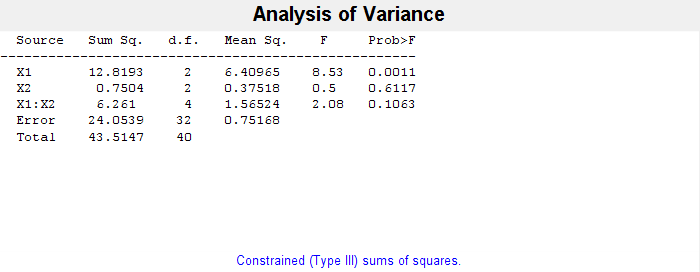


%logged stats
[P,T,STATS,TERMS]= anovan(log(taxa_zoo2),[dre_int2,dre_per2],'model','interaction');

8. we see that dredging intensity had a significant impact on total zooplankton density, let's investigate this trend further. Currently our taxa ID variable are numbers. Let's plot our most common taxa across dredging intensities



% SQL Query

sqlQuery = ['SELECT "taxaID", "intensityID", AVG("density") AS "average_density" ', ...
            'FROM public.densities ', ...
            'WHERE "taxaID" IN (22, 11, 7, 20, 25, 8, 19) ', ...
            'GROUP BY "taxaID", "intensityID" ', ...
            'ORDER BY "average_density" DESC'];

% Execute the query
cursor = exec(conn, sqlQuery);
cursor = fetch(cursor);

% Convert the fetched data to a table
resultTable = cursor.Data;

% Display the result table
disp(resultTable);

    {[22]}    {'1'}    {[636.1953]}
    {[22]}    {'0'}    {[457.4928]}
    {[22]}    {'2'}    {[159.6162]}
    {[11]}    {'1'}    {[144.0919]}
    {[11]}    {'0'}    {[106.8793]}
    {[ 7]}    {'1'}    {[ 72.8682]}
    {[20]}    {'0'}    {[ 50.9907]}
    {[ 7]}    {'0'}    {[ 37.9156]}
    {[11]}    {'2'}    {[ 35.3388]}
    {[20]}    {'2'}    {[ 33.1120]}
    {[20]}    {'1'}    {[ 31.8044]}
    {[25]}    {'0'}    {[ 22.2020]}
    {[25]}    {'1'}    {[ 15.6170]}
    {[ 7]}    {'2'}    {[ 14.8887]}
    {[ 8]}    {'0'}    {[ 12.7454]}
    {[ 8]}    {'2'}    {[ 12.1006]}
    {[ 8]}    {'1'}    {[ 12.0010]}
    {[19]}    {'0'}    {[  9.2894]}
    {[19]}    {'1'}    {[  2.4870]}
    {[25]}    {'2'}    {[  1.3002]}
    {[19]}    {'2'}    {[  0.8740]}




% % Close the cursor and connection
% close(cursor);
% close(conn);


9. Let's make a bar graph


% Assuming you have the 'resultTable' containing the data from the SQL query
% Extract data from the table
taxaID = resultTable(:, 1); % First column
intensityID = resultTable(:, 2); % Second column
average_density = resultTable(:, 3); % Third column

% Convert cell arrays to arrays
taxaID = cell2mat(taxaID);
intensityID = cell2mat(intensityID);
average_density = cell2mat(average_density);
average_density =log(average_density)+0.5

average_density =     6.9555
    6.6258
    5.5728
    5.4705
    5.1717
    4.7887
    4.4316
    4.1354
    4.0650
    3.9999


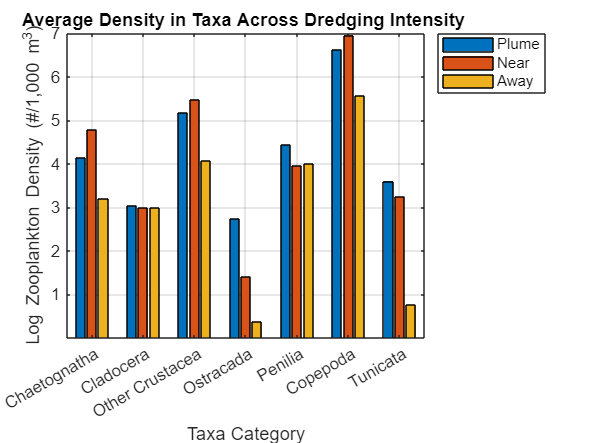

% Find unique taxaID and intensityID values
unique_taxaID = unique(taxaID);
unique_intensityID = unique(intensityID);

% Create a matrix to store bar data
bar_data = zeros(length(unique_taxaID), length(unique_intensityID));


% Fill bar_data with average_density values for each taxaID and intensityID
for i = 1:length(unique_taxaID)
    for j = 1:length(unique_intensityID)
        idx = taxaID == unique_taxaID(i) & intensityID == unique_intensityID(j);
        if any(idx)
            bar_data(i, j) = average_density(idx);
        end
    end
end


% Create the horizontal bar graph
figure;
bar2= bar(bar_data, 'grouped');


% Customize the plot
ylabel('Log Zooplankton Density (#/1,000 m^3)');
xlabel('Taxa Category');
yticks(1:length(unique_taxaID));
xticklabels({'Chaetognatha', 'Cladocera', 'Other Crustacea', 'Ostracada', 'Penilia','Copepoda', 'Tunicata'})
%xticklabels(string(unique_taxaID));
legend([bar2(1),bar2(2),bar2(3)],{'Plume', 'Near', 'Away'},'Location', 'bestoutside');
%legend(string(unique_intensityID), 'Location', 'bestoutside');
title('Average Density in Taxa Across Dredging Intensity ');
grid on;

Error Bars (work in progress)

% %CHAETOGNATHA
% % Calculate the length of the data
% n_cha_away_bef = length(average_density(intensityID == 0 & taxaID == 7));
% n_cha_near_bef = length(average_density(intensityID == 1 & taxaID == 7));
% n_cha_plume_bef = length(average_density(intensityID == 2 & taxaID == 7));
% 
% % Calculate the standard error
% se_cha_away_bef = std(log(average_density(intensityID == 0 & taxaID == 7))) / sqrt(n_cha_away_bef);
% se_cha_near_bef = std(log(average_density(intensityID == 1 & taxaID == 7))) / sqrt(n_cha_near_bef);
% se_cha_plume_bef = std(log(average_density(intensityID == 2 & taxaID == 7))) / sqrt(n_cha_plume_bef);
% 
% % Calculate the 95% confidence intervals
% cha_away_bef = se_cha_away_bef * 1.96;
% cha_near_bef = se_cha_near_bef * 1.96;
% cha_plume_bef = se_cha_plume_bef * 1.96;
% 
% %CLADOCERA
% % Calculate the length of the data
% n_cla_away_bef = length(average_density(intensityID == 0 & taxaID == 22));
% n_cla_near_bef = length(average_density(intensityID == 1 & taxaID == 22));
% n_cla_plume_bef = length(average_density(intensityID == 2 & taxaID == 22));
% 
% % Calculate the standard error
% se_cla_away_bef = std(log(average_density(intensityID == 0 & taxaID == 22))) / sqrt(n_cla_away_bef);
% se_cla_near_bef = std(log(average_density(intensityID == 1 & taxaID == 22))) / sqrt(n_cla_near_bef);
% se_cla_plume_bef = std(log(average_density(intensityID == 2 & taxaID == 22))) / sqrt(n_cla_plume_bef);
% 
% % Calculate the 95% confidence intervals
% cla_away_bef = se_cla_away_bef * 1.96;
% cla_near_bef = se_cla_near_bef * 1.96;
% cla_plume_bef = se_cla_plume_bef * 1.96;
% 
% %COPEPODA
% % Calculate the length of the data
% n_cop_away_bef = length(average_density(intensityID == 0 & taxaID == 22));
% n_cop_near_bef = length(average_density(intensityID == 1 & taxaID == 22));
% n_cop_plume_bef = length(average_density(intensityID == 2 & taxaID == 22));
% 
% % Calculate the standard error
% se_cop_away_bef = std(log(average_density(intensityID == 0 & taxaID == 22))) / sqrt(n_cop_away_bef);
% se_cop_near_bef = std(log(average_density(intensityID == 1 & taxaID == 22))) / sqrt(n_cop_near_bef);
% se_cop_plume_bef = std(log(average_density(intensityID == 2 & taxaID == 22))) / sqrt(n_cop_plume_bef);
% 
% % Calculate the 95% confidence intervals
% cop_away_bef = se_cop_away_bef * 1.96;
% cop_near_bef = se_cop_near_bef * 1.96;
% cop_plume_bef = se_cop_plume_bef * 1.96;
% 
% ci_vec=[cha_plume_bef,cha_near_bef,cha_away_bef,cla_plume_bef,cla_near_bef,cla_away_bef,cop_plume_bef,cop_near_bef,cop_away_bef];

error bars (alt method, work in progress)

% % Assuming you have the necessary variables defined
% taxa_values = [7, 22, 22]; % Taxa values for Chaetognatha, Cladocera, and Copepoda
% taxa_labels = {'CHA', 'CLA', 'COP'}; % Labels for taxa
% tot_dre_intensity_values = [0, 1, 2]; % List of intensity values
% 
% % Preallocate arrays to store results
% ci_vec = zeros(1, length(taxa_values) * length(tot_dre_intensity_values));
% 
% idx = 1; % Index to keep track of the current position in ci_vec
% 
% for t = 1:length(taxa_values)
%     taxa = taxa_values(t);
% 
%     for i = 1:length(tot_dre_intensity_values)
%         tot_dre_intensity = tot_dre_intensity_values(i);
% 
%         % Calculate the length of the data
%         n_data = length(average_density(intensityID == tot_dre_intensity & taxaID == taxa));
% 
%         % Calculate the standard error
%         se_data = std(log(average_density(intensityID == tot_dre_intensity & taxaID == taxa))) / sqrt(n_data);
% 
%         % Calculate the 95% confidence interval
%         ci = se_data * 1.96;
% 
%         % Store the confidence interval in ci_vec
%         ci_vec(idx) = ci;
% 
%         % Increment the index
%         idx = idx + 1;
%     end
% end
% 
% % ci_vec now contains the 95% confidence intervals for each taxa and tot_dre_intensity combination


% % Create the horizontal bar graph
% figure;
% bar2= bar(bar_data, 'grouped');
% 
% 
% % Customize the plot
% ylabel('Log Zooplankton Density (#/1,000 m^3)');
% xlabel('Taxa Category');
% yticks(1:length(unique_taxaID));
% xticklabels({'Chaetognatha', 'Cladocera', 'Other Crustacea', 'Ostracada', 'Penilia','Copepoda', 'Tunicata'})
% %xticklabels(string(unique_taxaID));
% legend([bar2(1),bar2(2),bar2(3)],{'Plume', 'Near', 'Away'},'Location', 'bestoutside');
% %legend(string(unique_intensityID), 'Location', 'bestoutside');
% title('Average Density in Taxa Across Dredging Intensity ');
% grid on;